Schedule for today	 

- Run Simulink files with MATLAB program 

- Use iterative approach to edit values in a Model 

- Handling data in Simulink  

- Model referencing 

- Projects


$$25*\frac{d^2 }{\mathrm{d}t^2 }x+3*\frac{d}{\mathrm{d}t}x\;+4*x\;=5*u\left(t\right)\;\;\;\;\;\;\;\;t>0$$


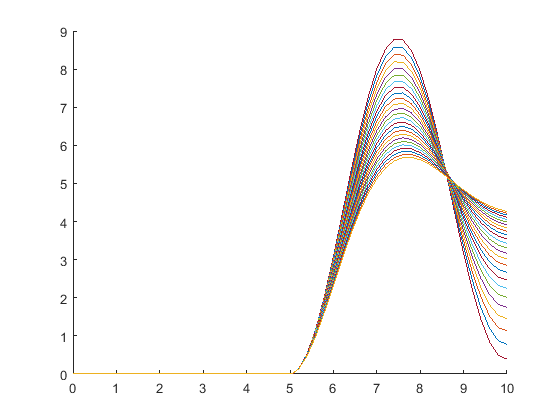

a = -3;
b = -4;
Kp = 36;
Ki = 4;
m = 25;
t = [0:0.01:10]';
Ts = 0.01;
stin = [zeros(floor((length(t)/2)+1),1) ; 5*ones(floor(length(t)/2),1)];
itr = 200;
clear yitr
for i = 1:25
    a = -i;
    sim('A1.slx')
    yitr(:,i) = yout;
    hold on
    plot(tout,yitr)
end
hold off